**Question: **

What amount of window area and wall area will provide the most energy per dollar over a 48 period of time?

Energy is determined by taking the integral of our energy function over time. The dollar amount is determined by the amount of wall and window area with their respective per meter material cost. 

**Why was this question chosen?**

     This question was chosen because we were curious to analyze the cost-benefit analysis of windows. Interestingly, windows allow a flow of radiation energy to enter a home, providing a free, carbon-neutral source of heating. However, windows are significantly more expensive than walls in terms of upfront, so we wondered if an additional stream of energy would make up for the higher material cost. We expanded further upon this question by even testing a range of window areas so we could analyze if there are anywhere upward or downward trends in total house energy per dollar. 

**Why is this question important?**

    This question is important through two important lenses: environmental and economic. Through an environmental lens, homes are being built for a changing climate. One where traditional heating methods such as burning large amounts of natural gas or using inefficient resistant heating are no longer viable as their carbon footprints far outweigh any benefit. In a bid for more self-sufficient heating, heating a home through solar radiation, even partly, has become an appealing option. In order to maximize a reduced reliance on carbon-intensive heating, this raises the question of what area of windows is needed for the most efficient (energy per dollar) house? In other words, how can funds be best spent to maximize the energy retention of a home?

     This question for what makes the most energy-efficient home goes hand in hand with what also makes the most economical home? Naturally, a more energy-efficient home conveys a home with a lower energy bill to heat it, if any. Therefore, there is a shared economic interest in answering what amount of window area will maximize energy per dollar? In short, will an additional window area provide enough of an energy flow to make up for its significantly higher upfront cost?

**Methodology/Model: **

We are going to answer the question by modeling the energy flows in and out of the house. The model is a model of Joseph’s actual house and his house’s actual window type and actual wall thickness, volume and surface area. It assumes there is no air loss through the house. It assumes that there is 500kg of wood inside the house on internal walls for thermal mass as well as piping filled with water. We are assuming that the outside temperature is -15 degrees C.  We are assuming that heat can only be lost through convection and conduction. And that the outside is forced convection because of the high winds we get in the area, and that the inside is natural convection. We are also assuming that every bit of energy that gets through the window is absorbed into the interior of the house. The model assumes all windows are facing directly south, and there are no other windows. There is a single interior room which goes 18ft floor to ceiling, and there are no rim joists or doors and the windows are closed. We added the thermal mass of the radiant floor heating built into the floor as well as the estimated mass of the wood.

We developed the model by assuming the wall was 2 separate parts that were equivalent to the surface temperature of that side of the wall and we did the same for the windows. So, we have an interior wall stock and an exterior wall stock.  We set the parameters by estimation of values, real value numbers such as thickness of a 2x6, looking up manufacturer numbers for the brand specific materials, such as Marvin windows and Rockwool insulation, and common knowledge for non brand specific materials, such as plywood. If we had more time, we would go to the actual house and test our model in order to validate. If we had more time we would also calculate all the windows on all the sides and how much sun they got.

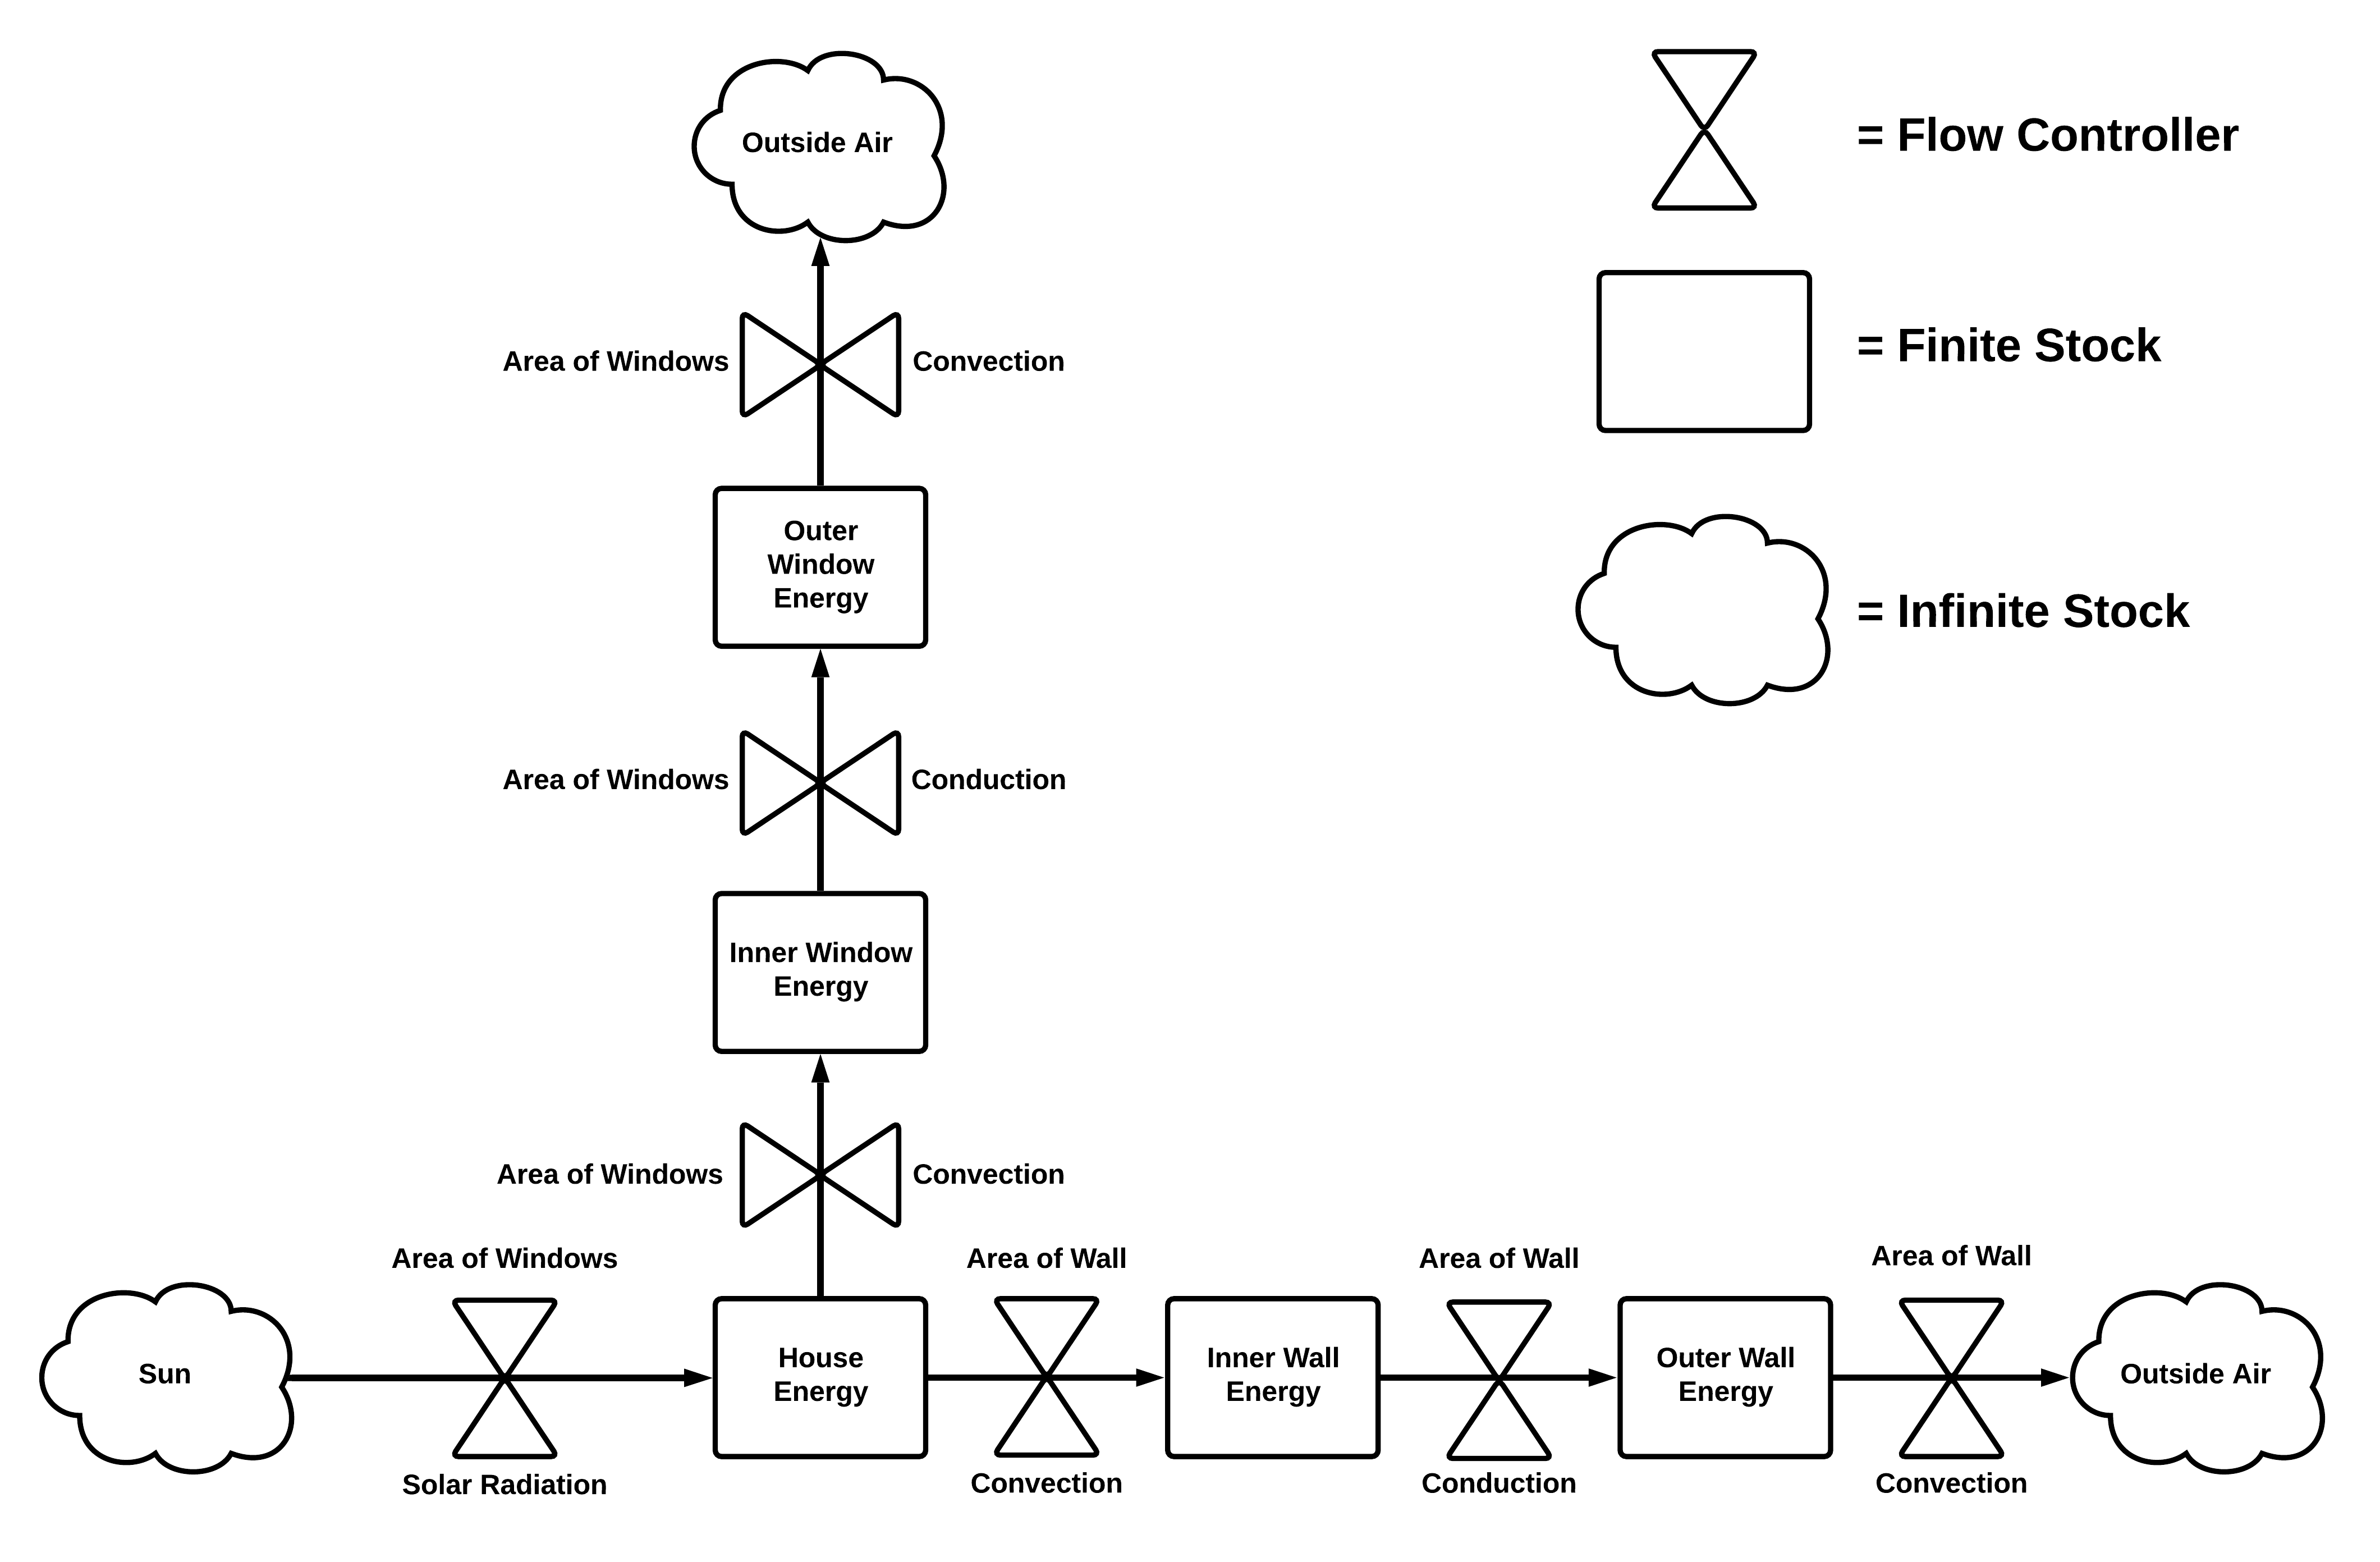

clear
clf
I_range = [.1 5 10 15 20 25 30 35 40]; %sweep of window area

%colors = ['#FF0000'; '#0000FF'; '#FF0000'; '#0000FF'; '#0000FF'];

JouleperDollar = ones([1, length(I_range)]);

for x = 1:length(I_range)
    I = I_range(x);
    [T_hour,M, cost] = HouseEnergy(I);
    hold on
    last2days = find(T_hour>(max(T_hour)-48));
    plot((T_hour(last2days)-max(T_hour)+48), M(last2days,1));% ,'Color', colors(x,:));
    minloc = find(M(:,1)==min(M(:,1)));% find location of the minimum temperature point and mark it on the plot
    %plot(T_hour(minloc), M(minloc,1),'*', 'Color', colors(x,:));
    mlen45 = (length(M)*4/5);
    JouleperDollar(x) = trapz(T_hour(last2days), (M(last2days,1))) / cost;
    temppercent(x) = (min(M(last2days,1))-288.706) / (cost);
end

Result:

The model showed that less windows provide better net energy per dollar. This result implies that the additional energy flow introduced by having windows was not enough to outweigh its lower thermal resistance to escaping energy and significantly higher per meter cost. 

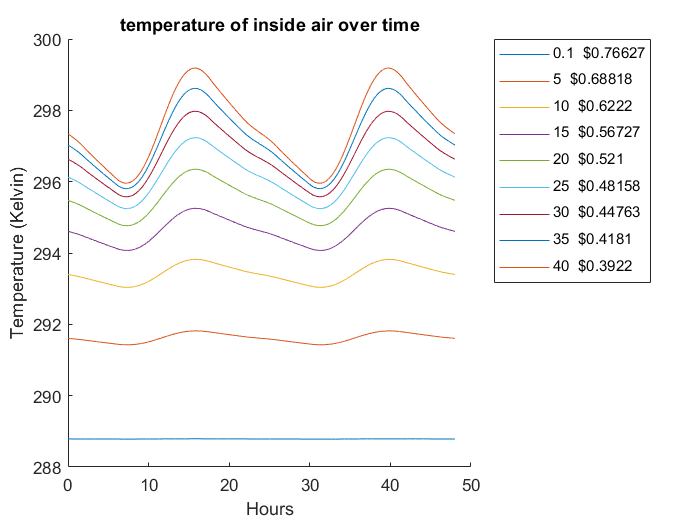

legend(string(I_range)+ " _ $" + string(JouleperDollar), "Location","bestoutside");
xlabel("Hours");
ylabel("Temperature (Kelvin)");
title("temperature of inside air over time")

The Legend represents surface area of window and the average temperature per cost.  